# Complex Flow

This is the complex flow that can be used with a conformal mapping to allow determination of flow around other objects. The simple flows will be tested first just for a sanity check before the full circulating cylinder and conformal mapping is used.

% Setup a test domain to test the analysis
max_domain_size = 2;
elem_along_axis = 200;
xpos = linspace(-max_domain_size, max_domain_size, elem_along_axis);
ypos = linspace(-max_domain_size, max_domain_size, elem_along_axis);

[xx, yy] = meshgrid(xpos, ypos);
zz = xx + 1j*yy;

## Simple Flow Tests

Simple tests to ensure that the stream functions being obtained are correct.

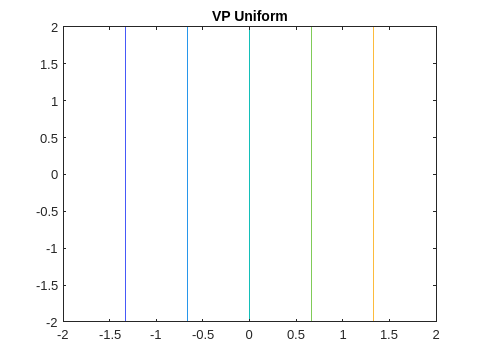

% Uniform flow pattern (complex)
fs_vel = 1.5; % Uniform flow velocity
fs_ang = 0*pi/180; % Uniform flow angle
w_uniform = cflow_uniform(fs_vel, fs_ang, zz);
[vp_uniform, sf_uniform] = flow_fields_from_cflow(w_uniform);

figure
contour(xpos, ypos, vp_uniform)
title('VP Uniform')

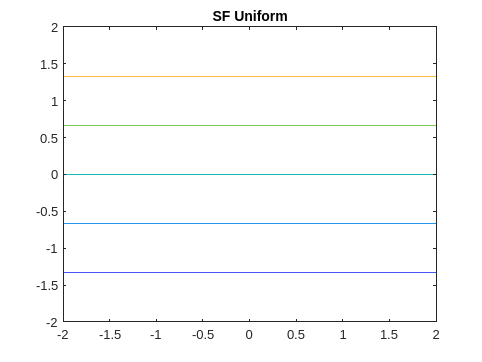

figure
contour(xpos, ypos, sf_uniform)
title('SF Uniform')

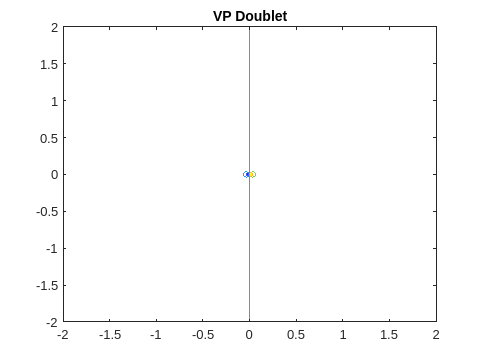

% Doublet flow pattern (complex)
doublet_str = 1.4;
w_doublet = cflow_doublet(doublet_str, zz);
[vp_doublet, sf_doublet] = flow_fields_from_cflow(w_doublet);

figure
contour(xpos, ypos, vp_doublet);
title('VP Doublet')

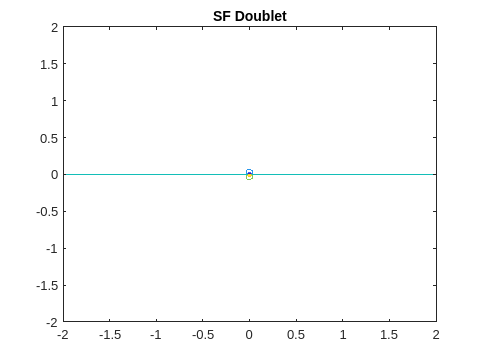

figure
contour(xpos, ypos, sf_doublet);
title('SF Doublet')

% Vortex flow pattern (complex)
vortex_str = 0;
w_vortex = cflow_vortex(vortex_str, zz);
[vp_vortex, sf_vortex] = flow_fields_from_cflow(w_vortex);

figure
contour(xpos, ypos, vp_vortex);

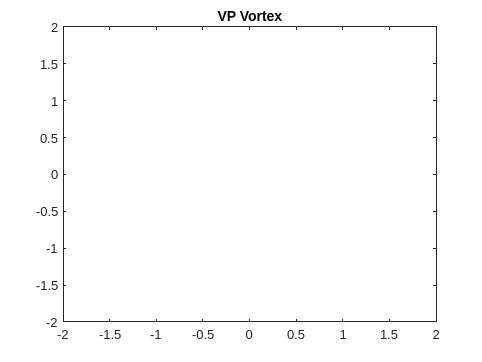

title('VP Vortex')

figure
contour(xpos, ypos, sf_vortex);

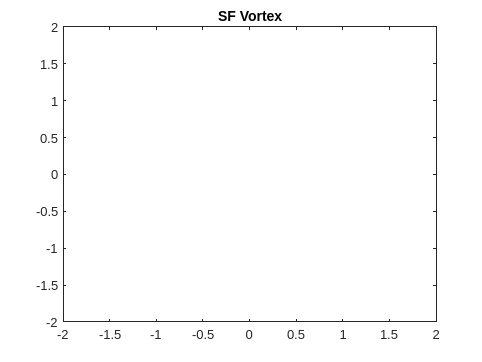

title('SF Vortex')

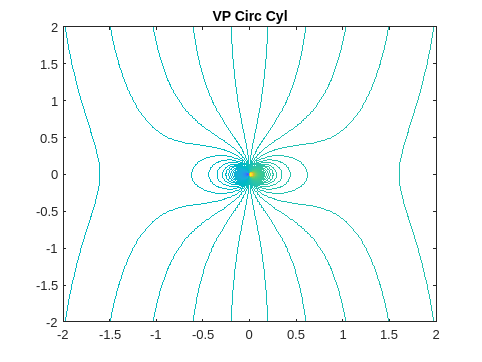

% Circulating cylinder (complex)

% Comprised of a doublet located at the origin, vortex, and uniform flow
% (with strengths to be determined later via the Kutta condition)

fs_vel = 4; % Uniform flow velocity
fs_ang = 0*pi/180; % Uniform flow angle
circ_rad = 1; % radius of circle to transform
doublet_str = fs_vel*(circ_rad)^(2);
% vortex_str = 1;

% Finds the appropriate vortex strength to place the rear stagnation point
% at the desired location
sp_ang = 0*(pi/180); % Angle of stagnation point
vortex_str = -circ_rad*exp(1j*sp_ang)*(fs_vel*exp(-1j*fs_ang) - doublet_str/circ_rad^2*exp(-1j*2*sp_ang))*1j;

% vortex_str = 0;

w_circ_cyl = cflow_circ_cyl(fs_vel, fs_ang, doublet_str, vortex_str, zz);
[vp_circ_cyl, sf_circ_cyl] = flow_fields_from_cflow(w_circ_cyl);

figure
contour(xpos, ypos, vp_circ_cyl, 200);
title('VP Circ Cyl')

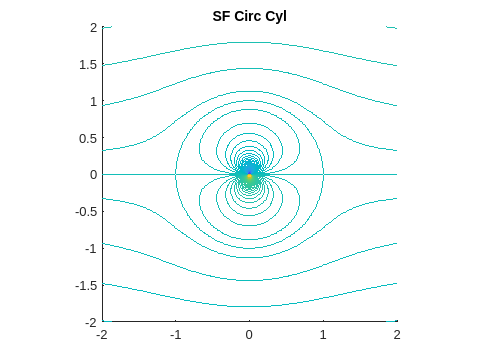

figure
hold on
axis equal
contour(xpos, ypos, sf_circ_cyl, 200);
contour(xpos, ypos, sf_circ_cyl)
title('SF Circ Cyl')

## Velocity Field

Computes the velocity at all points using a numerical finite difference. An additional function removes the data within the center so as to not show ridiculously large data points given the high rate of change of the flow function with decreasing distance from the origin (and center of the doublet).

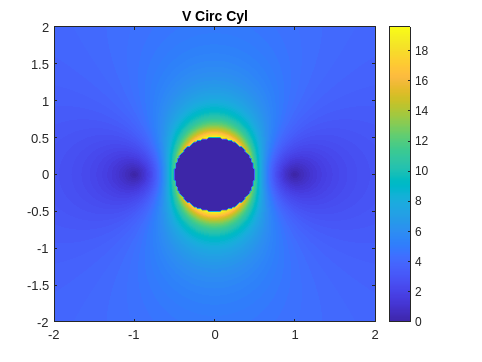

dw_dz = calc_cflow_deriv(w_circ_cyl, zz);
dw_dz_zeroed = zero_out_of_ring(dw_dz, zz, 0.5, 3);
[u, v, V] = flow_vels_from_cflow_deriv(dw_dz_zeroed, 0);

figure
axis equal
contourf(xpos, ypos, V, 100, 'LineColor', 'none');
title('V Circ Cyl')
colorbar

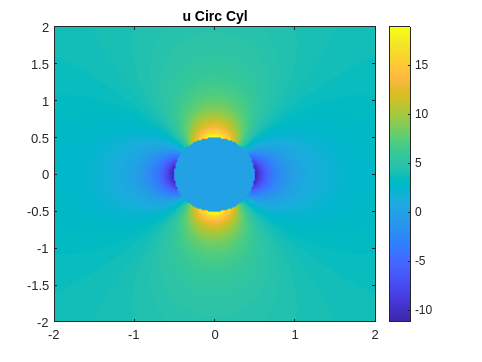


figure
axis equal
contourf(xpos, ypos, u, 100, 'LineColor', 'none');
title('u Circ Cyl')
colorbar

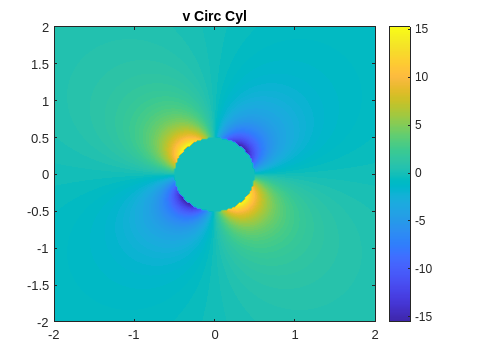


figure
axis equal
contourf(xpos, ypos, v, 100, 'LineColor', 'none');
title('v Circ Cyl')
colorbar

Attempt calculating the pressure profile from Bernoulli's equation (while ignoring the effect of gravity).

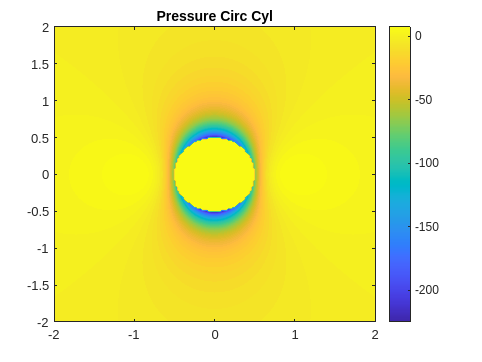

dens = 1.2; % kg/m^3
ref_pressure = 0; % gauge pressure
ref_vel = fs_vel; % free stream velocity
pressure = calc_pressure_no_grav_bern(dens, V, ref_vel, ref_pressure);

figure
axis equal
contourf(xpos, ypos, pressure, 100, 'LineColor', 'none');
title('Pressure Circ Cyl')
colorbar